**RobotCodeTemplate.mlx is a template for future FundRobo USB Camera Code**

This is a simple color object tracking USB Camera Tutorial.

This example shows how to use the snapshot function to acquire live images from USB webcams. To use it you will need the **MATLAB Support Package for USB Webcams**

Jack Levitsky and CJ Hilty (in spirit), 4/4/2022, Revision #A

clc             %clear command window
clear           %clear MATLAB workspace
imaqreset       %clear all image objects from memory

**Set up robot control system **(code that runs once)

%Identifying available webcams
camList=webcamlist

camList = 2×1 cell array
    {'Integrated Webcam'            }
    {'Microsoft® LifeCam Cinema(TM)'}


%Set up connection to the USB webcam, printing its properties
robotCam=webcam(2)

robotCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
               Brightness: 100
                     Zoom: 0
                Sharpness: 25
                 Exposure: -6
         WhiteBalanceMode: 'auto'
                      Pan: 0
                     Tilt: 0
                FocusMode: 'auto'
             WhiteBalance: 4500
                 Contrast: 5
                    Focus: 3
               Saturation: 83
    BacklightCompensation: 5
             ExposureMode: 'auto'


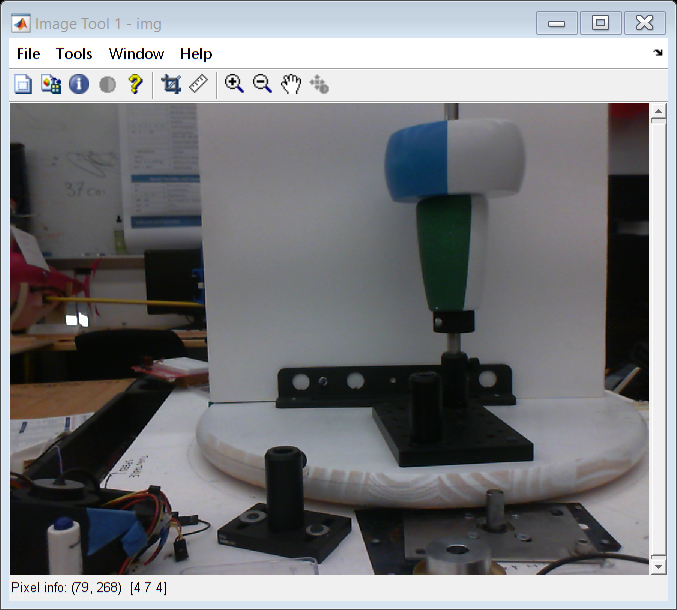


%Fix auto exposure problems by setting it to manual mode. Auto exposure and
%white balance are constantly changing/adapting to their environments. This
%makes computer vision algorithms very confused.
SETUPUSBCAMERA(robotCam);

%Preview video stream
preview(robotCam)
%Manually test camera is operational
gCamTest= input("Move hand in front of camera, type G, then hit ENTER","s");
clc;

%close preview window
closePreview(robotCam);

% Acquire a frame
img= snapshot(robotCam);

%Display the frame in the imaqtool window
%imaqtool launches an interactive GUI to allow you to explore, configure,
%and acquire tata from your installed and supported image acquisition
%devices
imtool(img);

% explore image with tool
gCamTest= input("experiment with tool, type G, then hit ENTER ", "s");

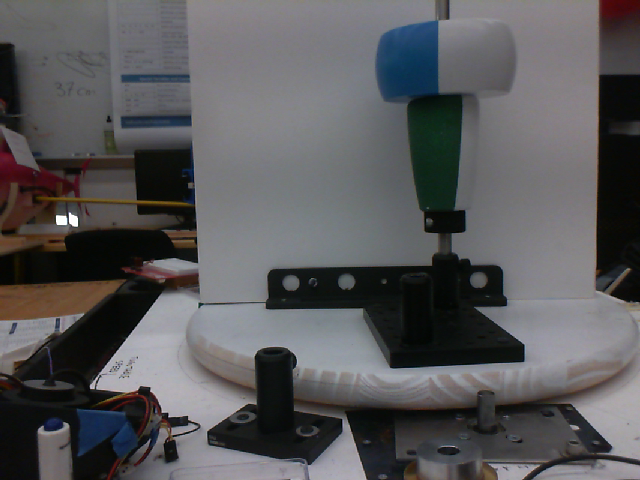


% Livescripts do some strange things when you try to update inline images
% quickly, so create a free floating figure to deal with that problem.
camWindow = figure('name', 'Robot USB Camera', 'NumberTitle','off','Visible','on');
figure(camWindow);                  % move focus to camWindow to show image
imshow(img,'Border','tight');
%Configure a loop to collect n data data points of camera captures

nTests = input(["Enter small number of camera tests, then hit enter:"]);


clc; % clear command window

r = rateControl(0.1);       % Create 0.1 hz loop rate
reset(4);                   % reset loop time to zero

Error using reset
Input was not a valid graphics object.

**Run robot control loop **(code that runs over and over)

controlFlag = 1;           %create a loop control

while (controlFlag <= nTests)
     robotIMG = SENSE(robotCam); %Get data from robot camera
     figure(camWindow);          % go to camWindow to show image
     image(robotIMG);            % show image in camWindow figure

        THINK(time);    %Compute what robot should do next
        ACT(time);      %Command robot actuators
camtest = input("move object to new position, type G, then hit ENTER (with FORCE)",'s')
clc;

waitfor(r);
controlFlag = controlFlag+1;
end

### **Mission data processing**

For many robot applications, you will need to post-process the data collected after the mission. Here we will plot the measured versus actual range positions.

%You should probably write some code to download images to a folder you can
%work on them later in

### **Clean shut down**

clc
clear robotCam        %Connection is no longer needed, clear the cam variable

**Robot Functions** (store the code's local functions here)

To make things readable, modular, and reusable, your main robot code is as brief as possible while the majority of work is completed by functions

function CONTROL_LOOP_INPUT(time)
    disp('Robot Running, control+c to stop')
    fprintf('The loop time is %d, \n', time)
end

**Sense Functions **(store all sense related functions here)

function []=SETUPUSBCAMERA(robotCam)
%SETUPUSBCAMERA creates and configures a webcam to be a simple robot vision
%system. It requires a standard webcam attached to your computer and takes
%webcam object name as its sole input.
%You need to set your camera's unique parameters to optimize the picture.

%Fix autoexposure and set it to manual, set whitebalance manual too
%robotCam.ExposureMode = "manual";
robotCam.WhiteBalanceMode="manual";
%Experimentally determine best exposure setting for lab, enter here
%robotCam.Exposure = ;
robotCam.Brightness=100;
end

function [robotImage]=SENSE(robotCam)
    %This function acquires a single image from the USBCamera testCam
    %and displays it in a stand alone figure

    robotImage=snapshot(robotCam);

end

**Think Functions **(store all think related functions here)

function THINK(time)
%I want death
end

**Act Functions **(store all act related functions here)

function ACT(time)
end
